# ECG Electrodes and electronics

Copyright (C) 2021 Miodrag Bolic

 This program is free software: you can redistribute it and/or modify   it under the terms of the GNU General Public License as published by  the Free Software Foundation, either version 3 of the License, or  (at your option) any later version.  This program is distributed in the hope that it will be useful, but WITHOUT ANY WARRANTY; without even the implied warranty of MERCHANTABILITY or FITNESS FOR A PARTICULAR PURPOSE.  See the GNU General Public License for more details <https://www.gnu.org/licenses/>. 

This code was developed by Miodrag Bolic for the book PERVASIVE CARDIAC AND RESPIRATORY MONITORING DEVICES: [https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING](https://github.com/Health-Devices/CARDIAC-RESPIRATORY-MONITORING) 

Dependencies: ecg.mat, AmplifyFilterDryElectrodes.slx, AmplifyFilterDryElectrodesCM.slx

% Changing the path from main_folder to a particular chapter
main_path=fileparts(which('Main_Content.mlx'));
if ~isempty(main_path)
    %addpath(append(main_path,'/Chapter2'))
    cd (append(main_path,'/Chapter7/ECGFrontEnd'))
    addpath(append(main_path,'/Service'))
end
SAVE_FLAG=0; % saving the figures in a file

## Introduction

In this notebook we will show different ECG circuits and introduce driven right leg circuit. Let us first import the ECG signal:

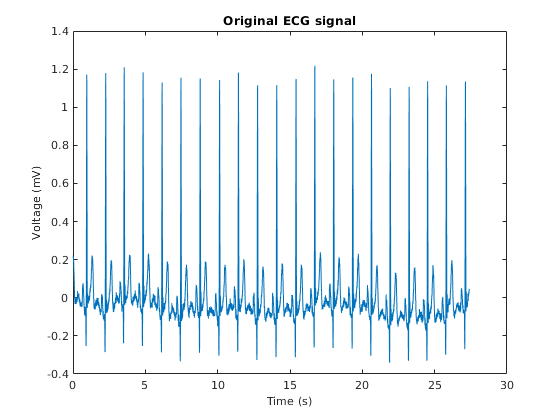

load('ecg1.mat')
fs=250;
fs_simulink=1000;
qrs(:,2)=(ecg/1000)/2;  % * 2 is because we are adding two ECG signals in Simscape
qrs(:,2)=qrs(:,2)-mean(qrs(:,2));
qrs(:,1)=1/fs:1/fs:length(ecg)/fs;
figure
plot(qrs(:,1), qrs(:,2)*1000*2) % * 2 is because we are adding two ECG signals in Simscape
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (mV)', 'FontSize', 10)
title('Original ECG signal')
xlim([0,30])

annonation_save('a)',"Fig7.10a.jpg", SAVE_FLAG);


## Dry electrodes, no common mode voltage, same electrode-skin interface


model_name = 'AmplifyFilterDryElectrodesNoElectModel';
open_system(model_name);

s=sim(model_name);

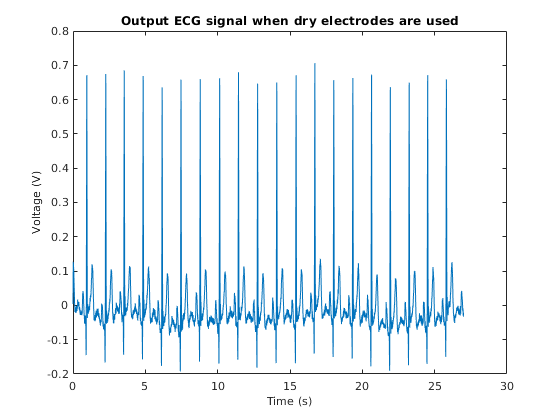


figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG signal when dry electrodes are used')

annonation_save('b)',"Fig7.10b.jpg", SAVE_FLAG);
PowerRatio=spectrum_ratio(fs_simulink, s.Vout.Data)

## Dry electrodes, no common mode voltage, same electrode-skin interface, adding DC bias


model_name = 'AmplifyFilterDryElectrodes';
open_system(model_name);

Bias of 100 mV.

qrs(:,2)=qrs(:,2)+0.1;


s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG signal with dry electrodes and a DC ofset of 100 mV')
annonation_save('',"Fig7.12.jpg", SAVE_FLAG);

Bias of 200 mV.

qrs(:,2)=qrs(:,2)+0.2;
s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG Signal')

## Dry electrodes, no common mode voltage, different electrode-skin interface

%load('ecg.mat')
qrs(:,2)=(ecg/1000)/2;
model_name = 'AmplifyFilterDryElectrodes';
open_system(model_name);
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Rep','R','300')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelRA/Rep','R','300')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Cep','C','0.02')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelRA/Cep','C','0.02')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Vh','v0','230')
set_param('AmplifyFilterDryElectrodes/Zero','Value','0')
s=sim(model_name);

figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG Signal')

Even though the skin impedance under the RA and LA electrodes changed and sweat component is included, the output did not change much.

PowerRatio=spectrum_ratio(fs_simulink, s.Vout.Data)

Case 2: Vh of the electrodes are different

set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Rep','R','1')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelRA/Rep','R','1')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Cep','C','5')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelRA/Cep','C','5')
set_param('AmplifyFilterDryElectrodes/Zero','Value','0')
set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Vh','v0','210')
s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG Signal')

Even though the skin impedance under the RA and LA electrodes changed and sweat component is included, the output did not change much.

set_param('AmplifyFilterDryElectrodes/DryElectrodeSkinModelLA/Vh','v0','230')
PowerRatio=spectrum_ratio(fs_simulink, s.Vout.Data)

## Dry electrodes, common model voltage no Driven Right Leg Circuit

In this case we consider a situation where dispacement current flows through the body. The current is modelled as 60 Hz sine wave signal with 0.2 uA DC value and 0.1 V amplitude. Body's resistance is set to 100 kOhms. This results in a signal shown in the second figure. No driven right leg circuit was used.

clear out s
model_name = 'AmplifyFilterDryElectrodesCM';


Let us consider a circuit without the third electrode and DRL circuit

set_param('AmplifyFilterDryElectrodesCM/Rb','Commented','off')
set_param('AmplifyFilterDryElectrodesCM/DryElectrodeSkinModelRL','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/DRL_Feedback','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/GND4','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/GND2','Commented','off')
open_system(model_name);
s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG Signal')

figure
plot(s.CM.Time, s.CM.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output Common mode signal')
xlim([0,3])

## Dry electrodes without Driven Right Leg Circuit

Let us consider a circuit with the third electrode and without DRL circuit.

In this case we consider a situation where dispacement current flows through the body. The current is modelled as 60 Hz sine wave signal with 0.2 uA DC value and 0.1 V amplitude. Third electrode is used and it is connected to the ground. This results in a signal shown in the second figure. No driven right leg circuit was used.

clear out s
model_name = 'AmplifyFilterDryElectrodesCM';

set_param('AmplifyFilterDryElectrodesCM/Rb','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/DryElectrodeSkinModelRL','Commented','off')
set_param('AmplifyFilterDryElectrodesCM/DRL_Feedback','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/GND4','Commented','off')
set_param('AmplifyFilterDryElectrodesCM/GND2','Commented','on')
open_system(model_name);


s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG signal without driven right leg circuit')
annonation_save('a)',"Fig7.14a.jpg", SAVE_FLAG);

figure
plot(s.CM.Time, s.CM.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Mixed common mode and ECG signal')
xlim([0,3])
annonation_save('b)',"Fig7.14b.jpg", SAVE_FLAG);
PowerRatio=spectrum_ratio(fs_simulink, s.Vout.Data)

## Dry electrodes with Driven Right Leg Circuit

Let us consider a circuit with the third electrode and without DRL circuit

model_name = 'AmplifyFilterDryElectrodesCM';
open_system(model_name);
set_param('AmplifyFilterDryElectrodesCM/Rb','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/DryElectrodeSkinModelRL','Commented','off')
set_param('AmplifyFilterDryElectrodesCM/DRL_Feedback','Commented','off')
set_param('AmplifyFilterDryElectrodesCM/GND4','Commented','on')
set_param('AmplifyFilterDryElectrodesCM/GND2','Commented','on')


s=sim(model_name);
figure
plot(s.Vout.Time, s.Vout.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Output ECG signal with driven right leg circuit')
annonation_save('a)',"Fig7.16a.jpg", SAVE_FLAG);

figure
plot(s.CM.Time, s.CM.Data)
xlabel('Time (s)', 'FontSize', 10)
ylabel('Voltage (V)', 'FontSize', 10)
title('Mixed common mode and ECG signal')
xlim([0,3])
annonation_save('b)',"Fig7.16b.jpg", SAVE_FLAG);

It can be seen that the amplitude of the oscillations of the common mode voltage reduced from 0.1V to 0.0025V resulting in the reduction of common mode voltage by 40. 

PowerRatio=spectrum_ratio(fs_simulink, s.Vout.Data)

## Exersizes

Excersize 1: repeat the analysis for all cases after replacing dry electrode models with wet electrode models. Observe the results. 

Excersize 2: Analyze the effect of mismatch of the parameters of the electrodes (Rep, Cep, Vh) on the output ECG waveform as well as on the PowerRatio value in cases where there is no common mode voltage and in cases with common mode voltage.

Excersize 3: Consider textile electrodes that have very large impedance (assume 300 MOhms) and very low capacitance (assume 20 pF). How would behaviour of the system change is this case?

Excersize 4: Make ECG signal zero and consider only the reduction of common mode signal. How is common mode gain improved by changing the resistor Rf in the driven right leg circuit from 1 MOhm to 2 MOhm (5 MOhm)?

Excersize 5: Set tolerance of resistors R4-R7 to none. In this case, all the resistors will have the same values. Consider the cases where commom mode voltage exist and analyze if driven right leg circuit improves the result at the output. Comment your results. 

function PowerRatio=spectrum_ratio(fs, ecg)
% Define frequency ranges of interest fot the signal
Fmask_low_sig=5;
Fmask_high_sig=14;
Fmask_low_all=5;
Fmask_high_all=70;

% Compute periodogram
NyquistF = fs/2;
FResBPM = 0.5;
Nfft = (60*2*NyquistF)/FResBPM; %number of bins in power spectrum
[Pxx,F] = periodogram(ecg,hamming(length(ecg)),Nfft,fs);

% Compute power in the frequency band of the signal of interest
FMask1 = (F >= Fmask_low_sig)&(F <= Fmask_high_sig);
PowerSig = sum(Pxx(FMask1));

% Compute power in the total frequency band 
FMask2 = (F >= Fmask_low_all)&(F <= Fmask_high_all);
PowerAll = sum(Pxx(FMask2));

% Compute signal quality indices = ratio of the power in the 
PowerRatio=PowerSig/PowerAll;
end
